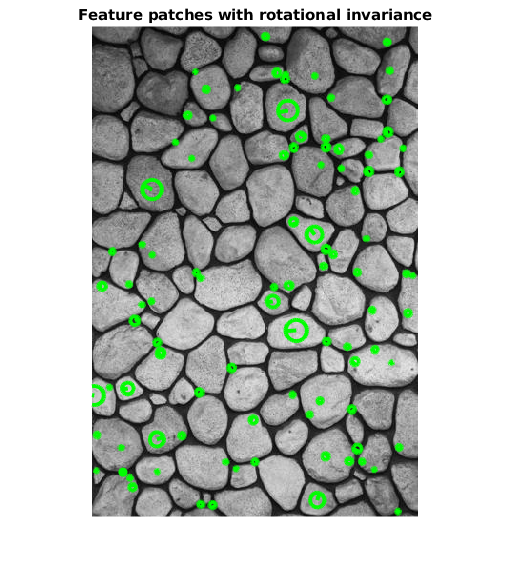

clear all; close all;

%VLFEATROOT = '/home/mlrosenquist/MATLAB Add-Ons/computer-vision-and-ml/vlfeat-0.9.21-bin/vlfeat-0.9.21';
%run([VLFEATROOT,'/toolbox/vl_setup.m']);

% Load image and convert to grayscale
Irgb = imread('stone.jpg');
I = rgb2gray(Irgb);

% Extract rotation invariant image patches using SIFT and vl_covdet
[f,d] = vl_sift(single(I)) ;
[frames, descrs] = vl_covdet(single(I), 'descriptor', 'patch','frames',f);

% Pick a random subset of features
nFeatures = 100;
featuresInds = randsample([1:size(frames,2)],nFeatures);
frames = frames(:,featuresInds);
descrs = descrs(:,featuresInds);

figure
imshow(I)
hold on ;
vl_plotframe(frames) ;
title('Feature patches with rotational invariance');

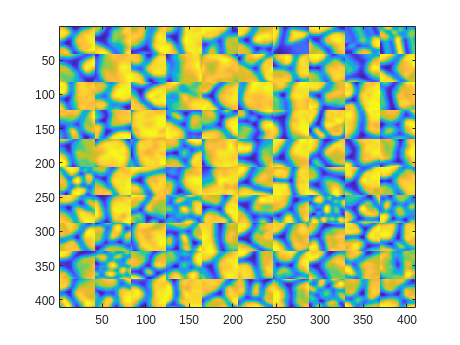


figure
w = sqrt(size(descrs,1)) ;
vl_imarraysc(reshape(descrs(:,1:nFeatures), w,w,[])) ;

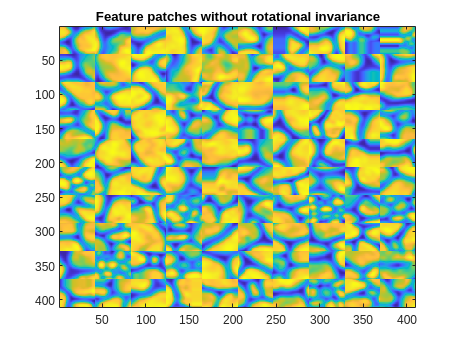


% Display the same features as above, but without rotation invariance
f(4,:) = 0; % Force all feature orientations to zero
[frames, descrs] = vl_covdet(single(I), 'descriptor', 'patch','frames',f);
frames = frames(:,featuresInds);
descrs = descrs(:,featuresInds);

figure
w = sqrt(size(descrs,1)) ;
vl_imarraysc(reshape(descrs(:,1:nFeatures), w,w,[])) ;
title('Feature patches without rotational invariance');